# Simscape Solver Mode Selection for Power Systems and Power Electronic Simulation

Copyright © 2022-2024, The MathWorks, Inc.

## Summary

In this session we will explore how different solvers act on power system simulations. Specifically, we will explore the trade-off between reduction of simulation time vs accuracy when switching to Frequency&Time mode in Simscape. 

## Solvers for Electromagnetic Transient (EMT) Simulation

With EMT simulations, accurate reconstruction of waveforms at the base frequency is a requirement. This requirement puts a limit on the largest step size that can be used to accurately capture EMT effects. The figure below shows reconstruction of a 60Hz waveform using 10, 50 and 200 fixed-step samples

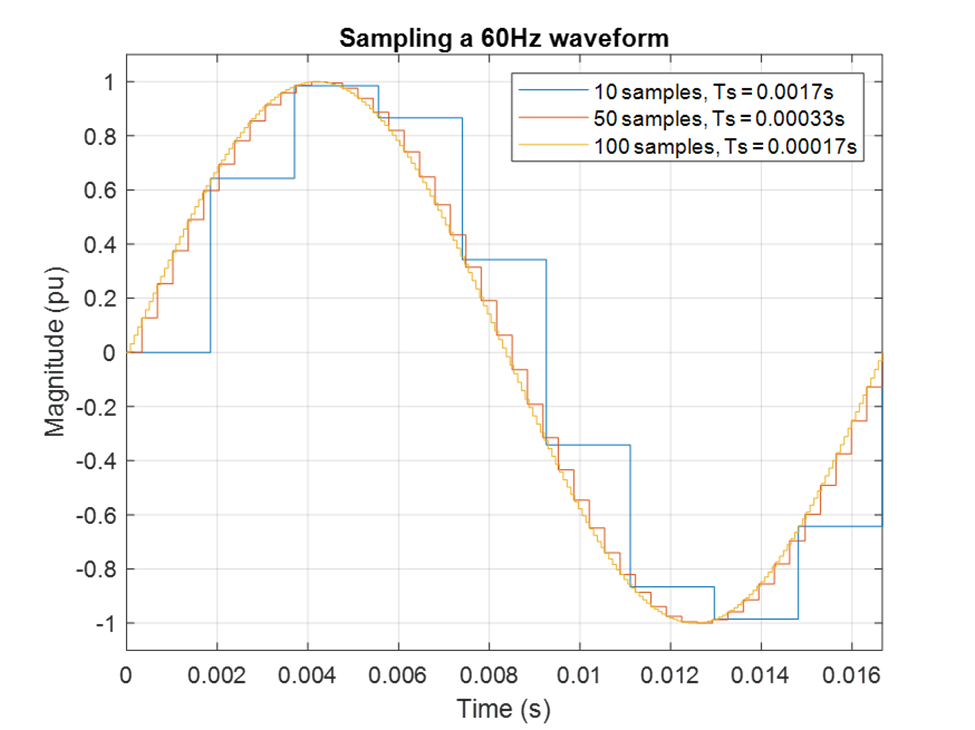

## Solvers for RMS Simulation

The figure shows a comparison of the response of a system when using a fixed-step solver and variable step solver. The fixed-step solver uses a time-step of 1 millisecond. The variable-step solver adapts its time step depending on the rate of change of the response. The response shown here is field voltage for a generator.

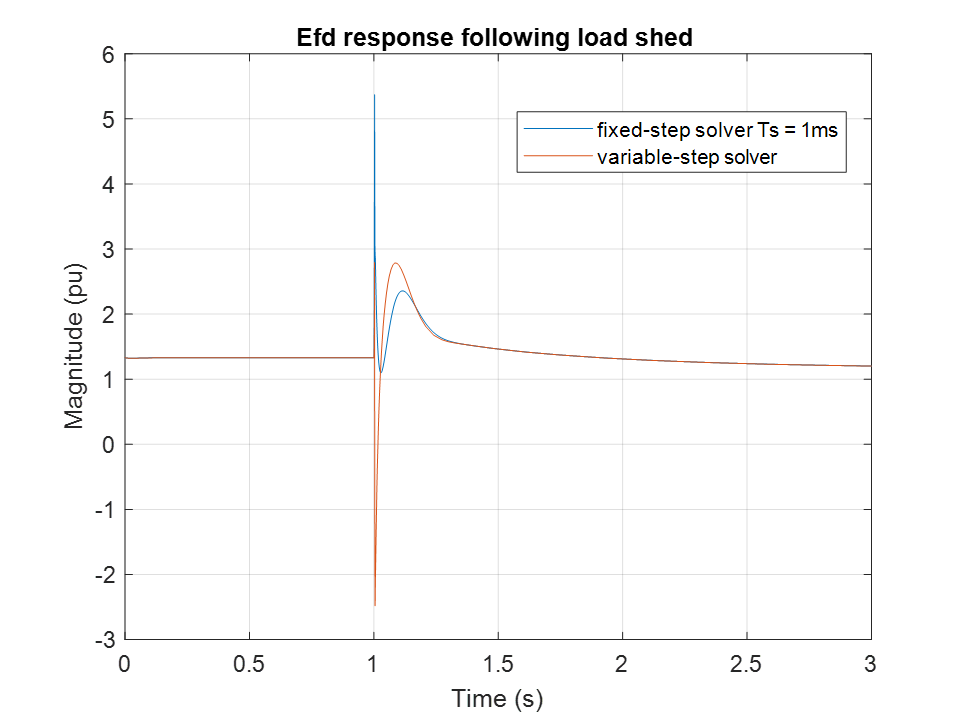

The figure below shows the variable-step solver time-steps overlaid on the field voltage response. You can see how the time-steps become smaller at the load change event, and larger as the rate of change of the response reduces.

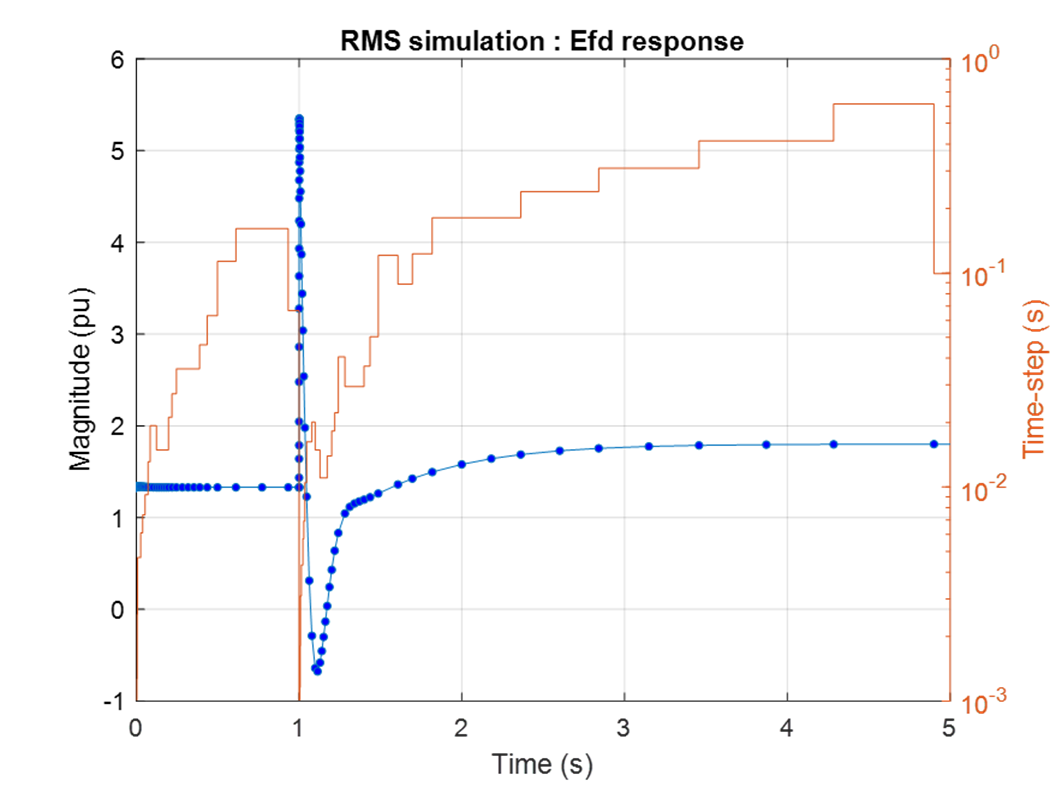

 In Simscape RMS is known as frequency-time equation formulation. In general, this formulation leads to accurate simulation of AC models using larger time steps than the traditional time formulation.

**Use frequency-time equation formulation** to speed up your simulation when:

- Your simulation contains **periodic AC signals with a common fundamental frequency**

- You are interested in the **slow-moving AC-related quantities**, such as amplitude or phase, and the **DC output signals**

## Limitations of Frequency & Time

**No AC Source present. Note that following do NOT count as a AC Source**

- VSC in gridforming mode

web(fullfile(docroot, 'slcontrol/ug/islanded-microgrid-using-droop-control.html?s_tid=doc_srchtitle'))

-  Grid represented as controlled voltage source

web(fullfile(docroot, 'sps/ug/single-phase-grid-connected-in-pv-system.html?s_tid=doc_srchtitle'))

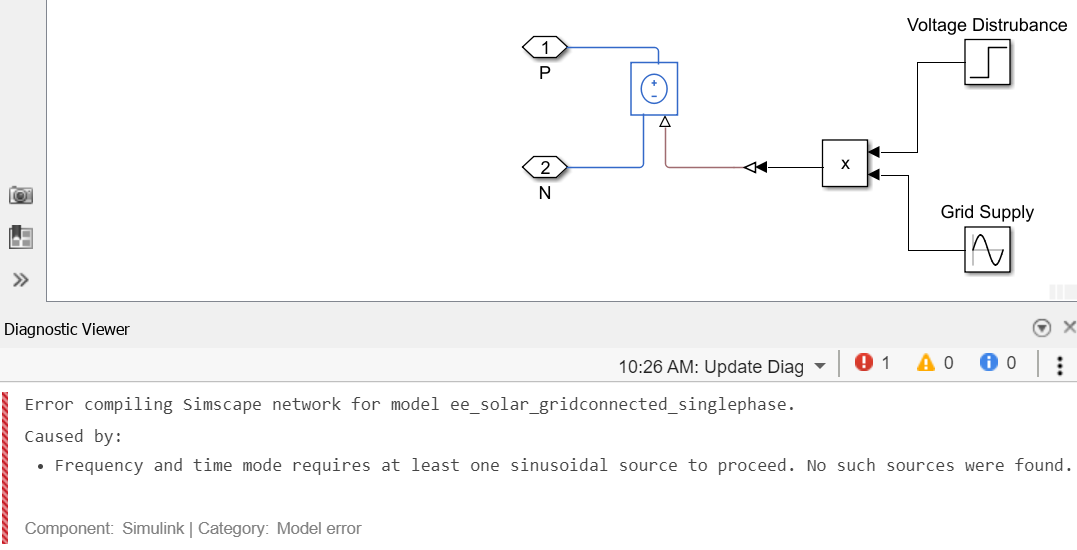

**Model can not be represented as switched linear equations**

- For the example model both the PV cell as well as the Average chopter cause issues.

web(fullfile(docroot, 'sps/ug/three-phase-grid-connected-in-pv-system.html?s_tid=doc_srchtitle'))

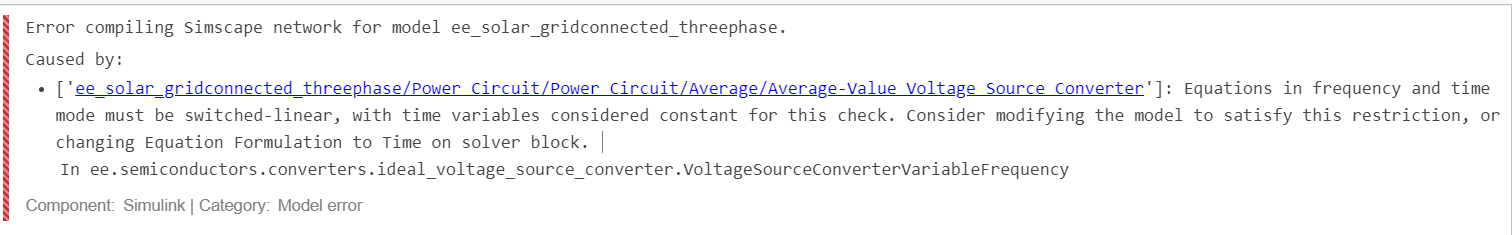

## Set up the model

To measure the time required to run a simulation, open the model *ee_sm_control* and create a model callback.

mdl = 'ee_sm_control_local';
open_system(mdl);
set_param(mdl,'SimscapeLogLimitData','off');
set_param(mdl,'ReturnWorkspaceOutputs',1);

## Run a time-based simulation

Double-click the Solver Configuration block and apply the following configuration:

- Enable the local solver by checking the **Use local solver** check box

- Set the `Sample time` parameter to $\frac{1}{f_{\textrm{Grid}\;} \cdot 100}=\frac{1}{60\textrm{Hz}\cdot 100}$

- Set the `Equation formulation` parameter to `Time`

You can also run this code to configure the block.

Ts = 1/60/100;
blk = char(find_system(mdl,'MaskType','Solver Configuration'));
set_param(blk,'UseLocalSolver','on');
set_param(blk,'LocalSolverSampleTime',num2str(Ts));
set_param(blk,'EquationFormulation','NE_TIME_EF');

Simulate the model and save the run time and logging variable.

out = sim(mdl);
tsim_time = round(out.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime,2);
simlog_ee_sm_control_time = out.simlog_ee_sm_control;

## Rerun time-based Simulation with larger sampling time (unrealistic large)

Ts = 1/60;
set_param(blk,'LocalSolverSampleTime',num2str(Ts));


Simulate the model and save the run time and logging variable.

out = sim(mdl);
tsim_time_fast = round(out.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime,2);
simlog_ee_sm_control_timeFast = out.simlog_ee_sm_control;

## Run a phasor-mode simulation

Double-click the Solver Configuration block and apply the following configuration:

- Enable the local solver by checking the `Use local solver` check box

- Set the `Sample time` parameter to  $\frac{1}{f_{\textrm{Grid}} }=\frac{1}{60\textrm{Hz}}$

- Set the `Equation formulation` parameter to `Frequency and time`

You can also run this code to configure the block.

blk = char(find_system(mdl,'name','Solver Configuration'));
set_param(blk,'UseLocalSolver','on');
set_param(blk,'LocalSolverSampleTime',num2str(Ts));
set_param(blk,'EquationFormulation','NE_FREQUENCY_TIME_EF');

For the Frequency&Time mode is recomended to avoid having breakers operation depending on zero crossings, otherswise the full performance potential of F&T is not utilized. 

set_param([mdl,'/Circuit Breaker Step off'],'breaker_behavior','ee.enum.switches.breakerBehavior.zeroCrossingDisable');
set_param([mdl,'/Circuit Breaker Step on'],'breaker_behavior','ee.enum.switches.breakerBehavior.zeroCrossingDisable')

Simulate the model and save the run time and logging variable.

out = sim(mdl);
tsim_phasor = round(out.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime,2);
simlog_ee_sm_control_phasor = out.simlog_ee_sm_control;

## Compare the model execution times

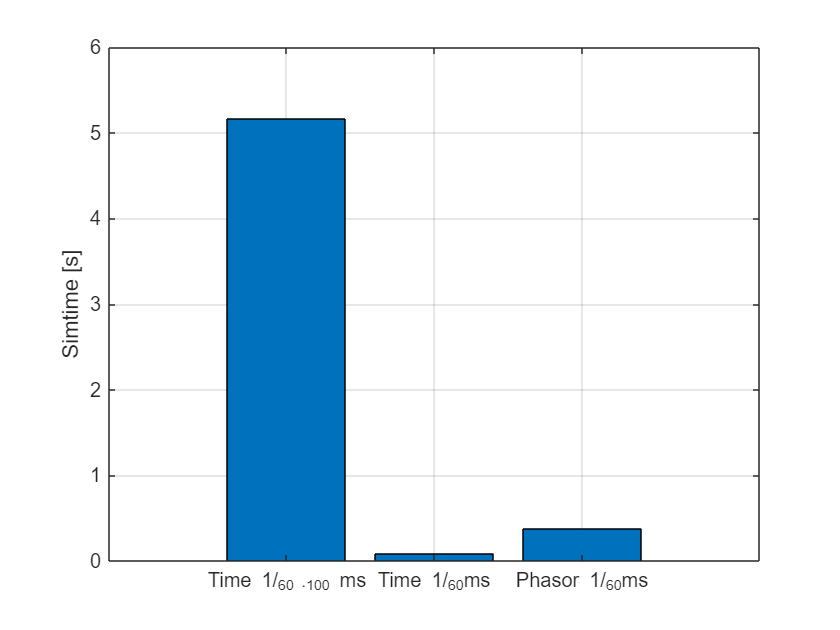


figure();
bar([tsim_time; tsim_time_fast; tsim_phasor])
ylabel('Simtime [s]')
grid on;
xticklabels({})
xticklabels({'Time {1}/_{60 \cdot100} ms','Time {1}/_{60}ms','Phasor {1}/_{60}ms'});

## Compare DC results

Plot the field voltage and rotor speed for both the time and frequency-time simulations. For each simulation mode, display markers at every 50 data points.

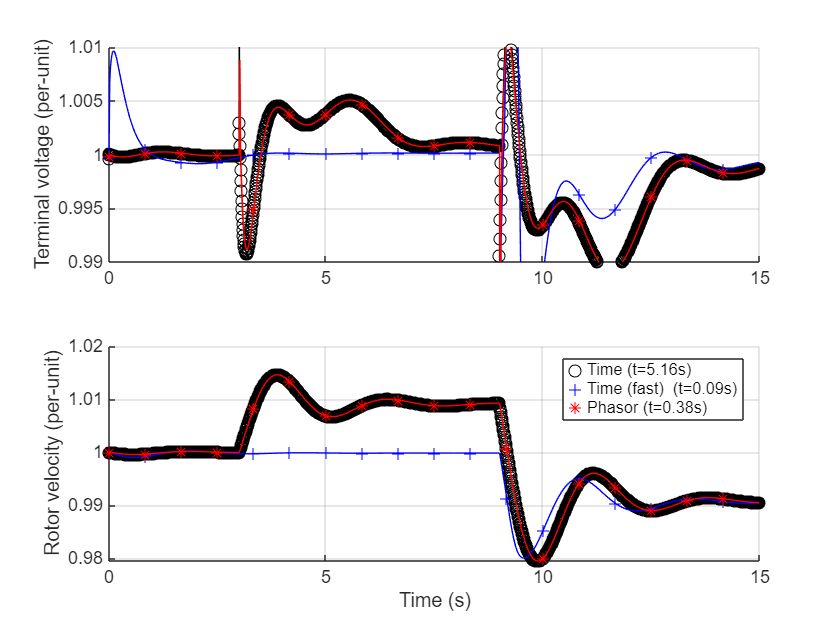

[hTime,hTimeFast,hPhasor]=setup_figure_local(simlog_ee_sm_control_time,simlog_ee_sm_control_timeFast,simlog_ee_sm_control_phasor,'dc');
legend([hTime,hTimeFast,hPhasor],{['Time (t=',num2str(tsim_time),'s)'],['Time (fast)  (t=',num2str(tsim_time_fast),'s)'],['Phasor (t=',num2str(tsim_phasor),'s)']});

The phasor simulation reproduces near-identical results as the time-based simulation, despite using a time step that is 10 times larger. The measured simulation time is also shown for each of the simulation modes in the plot legend. This performance indicator is different on different machines, but the frequency-time simulation should be about two times faster than the time simulation. Note that the actual time required per step is higher in the frequency-time case, but the overal time is reduced.

## Compare AC results

Plot the *a*-phase voltage of the synchronous machine over the time period `1s` to `1.1s`. Because of the larger time steps in the frequency-time formulation, the resolution of the AC quantity is too small to make out the sine wave. The points that are available are undersampled, but still accurate.

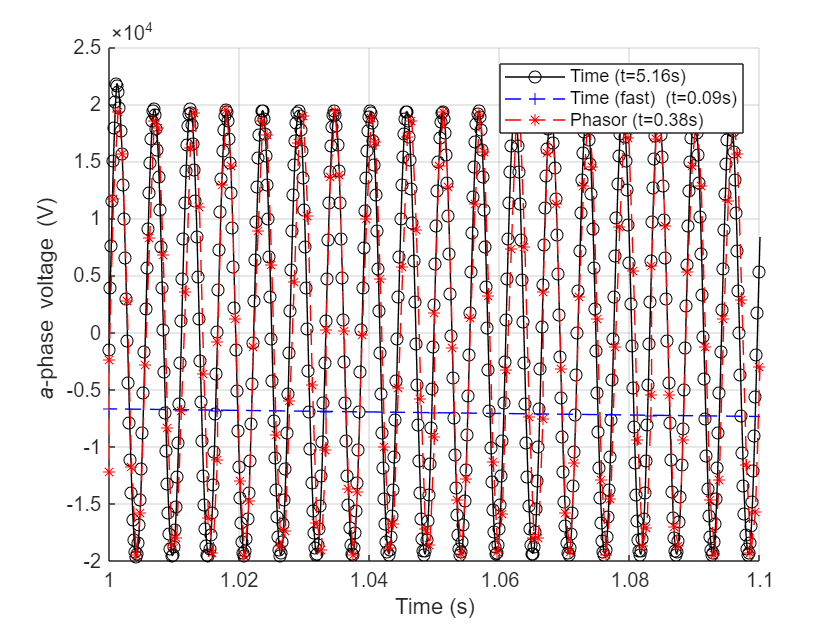

[hTime,hTimeFast,hPhasor]=setup_figure_local(simlog_ee_sm_control_time,simlog_ee_sm_control_timeFast,simlog_ee_sm_control_phasor,'ac');
legend([hTime,hTimeFast,hPhasor],{['Time (t=',num2str(tsim_time),'s)'],['Time (fast)  (t=',num2str(tsim_time_fast),'s)'],['Phasor (t=',num2str(tsim_phasor),'s)']});

In general, use frequency-time formulation to speed up simulations where the outputs of interest are DC or slow-moving AC quantities. You can use periodic sensors to measure slow-moving properties of AC signals such as amplitude and phase in both time and frequency time formulations. For more information, see the [PS Harmonic Estimator (Amplitude, Phase)](docid:simscape_ref#buvvkcd-1) block.

Sometimes there are small phase offsets between time- and frequency-time-generated AC signals. This difference is caused by the accumulated integration error of a slightly different signal frequency over time.

*Copyright 2022-2024 The MathWorks, Inc.*